# Potential Field Visualizations

Constructing the Potential Field

point_spacing = 0.2;

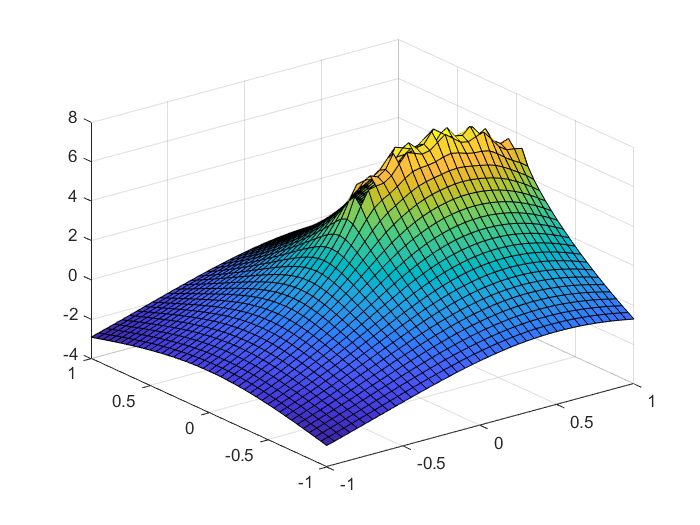

clf
bounds = -1:0.05:1;
[x, y] = meshgrid(bounds, bounds);

potential_func = make_potential_line([0, 0], [1, 0], point_spacing);
surf(x, y, potential_func(x, y));

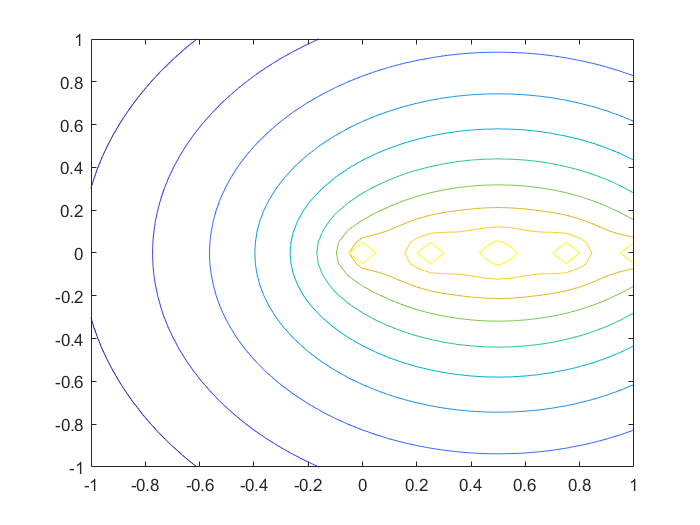

clf
test = potential_func(x, y);
contour(x, y, test)

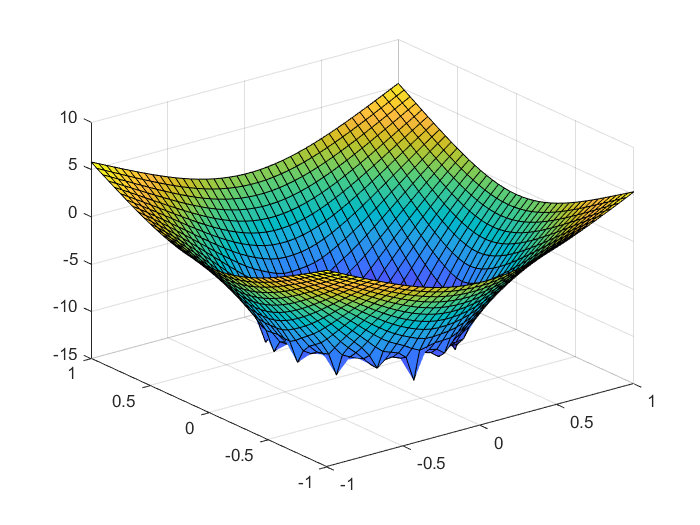

clf
potential_func = make_potential_BoB([0, 0], 0.5, point_spacing);
surf(x, y, potential_func(x, y));

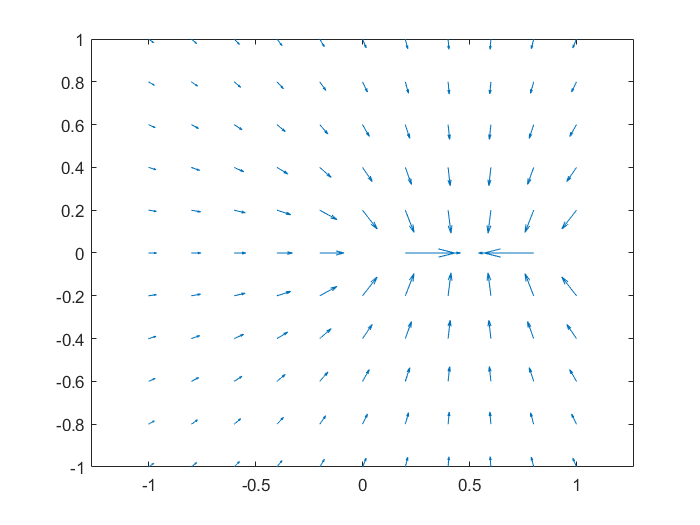

bounds = -1:0.2:1;
[x, y] = meshgrid(bounds, bounds);
grad_func = make_gradient_line([0, 0], [1, 0], point_spacing);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

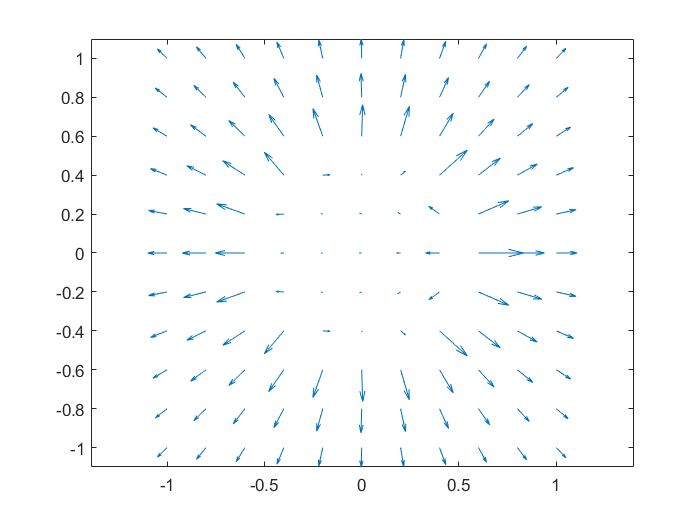

grad_func = make_gradient_BoB([0, 0], 0.5, point_spacing);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

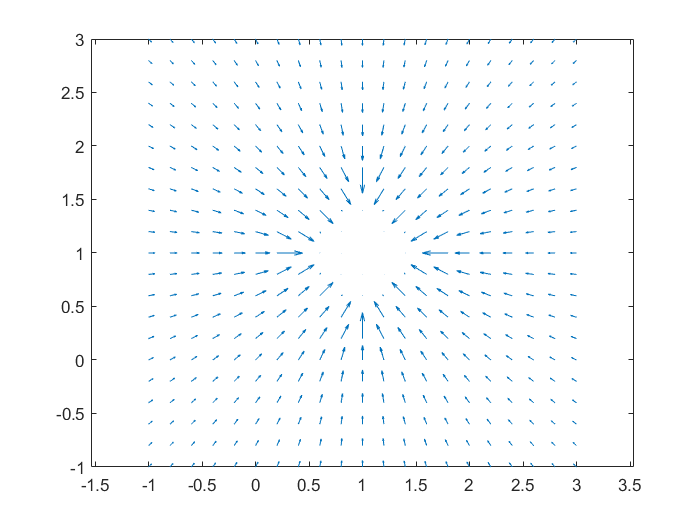

[potential_func, grad_func] = make_square(1, [1, 1], pi/4, point_spacing);

bounds = -1:0.2:3;
[x, y] = meshgrid(bounds, bounds);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

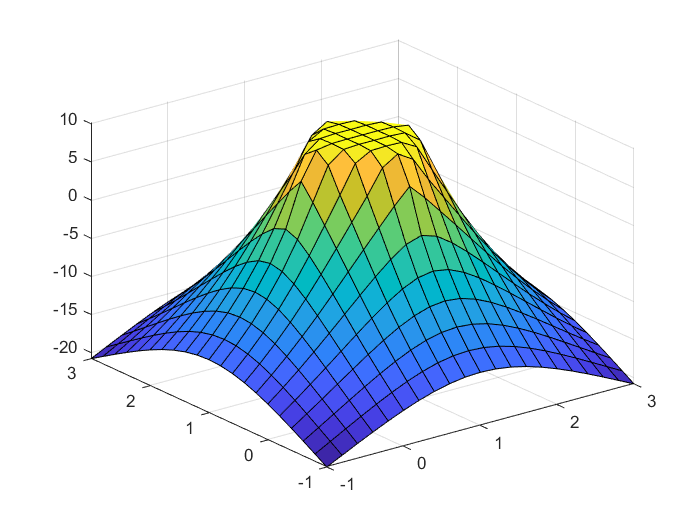


surf(x, y, potential_func(x, y));

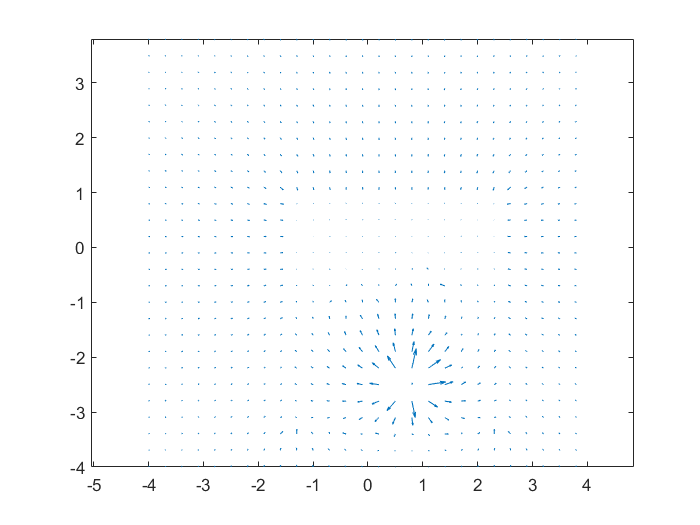

[potential_func, grad_func] = make_hardcoded_guantlet(point_spacing, 7);

bounds = -4:0.3:4;
[x, y] = meshgrid(bounds, bounds);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

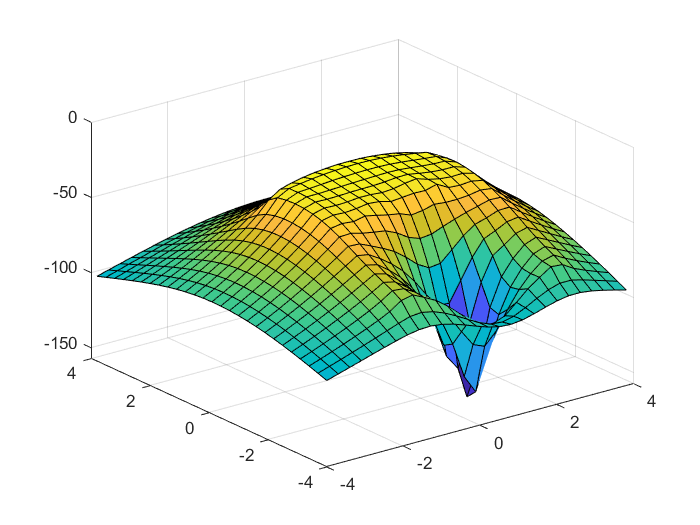


surf(x, y, potential_func(x, y));

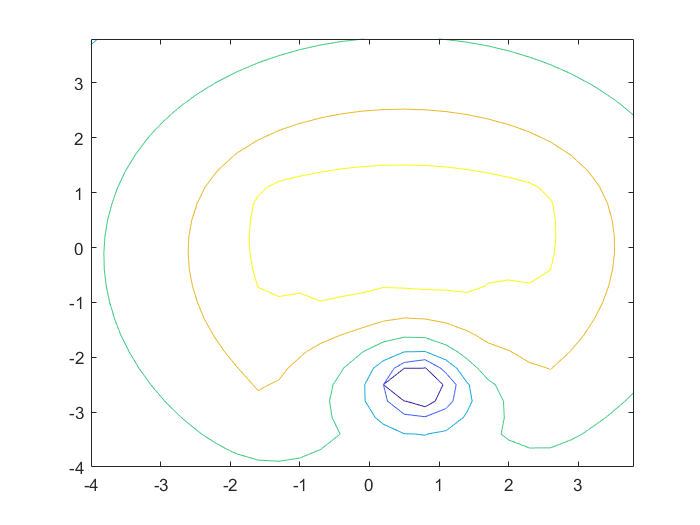

contour(x, y, potential_func(x, y))

grad_func(0,0)

ans = ans(:,:,1) =

    0.4653


ans(:,:,2) =

    4.5605


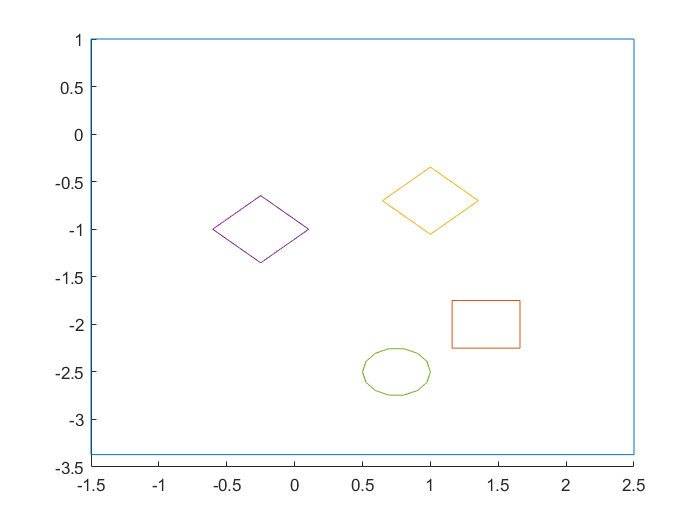

    % create walls
    w = draw_rectangle(4, 4.37, [0.5, -1.185], 0);
    % create box 1
    s1 = draw_rectangle(0.5, 0.5, [1.41, -2], 0);
    % create box 2
    s2 = draw_rectangle(0.5, 0.5, [1, -0.7], pi/4);
    % create box 3
    s3 = draw_rectangle(0.5, 0.5, [-0.25, -1], pi/4);
    % create BoB
    bob = draw_circle([0.75, -2.5], 0.25);
    clf
    hold on
    plot(w(:,1), w(:,2))
    plot(s1(:,1), s1(:,2))
    plot(s2(:,1), s2(:,2))
    plot(s3(:,1), s3(:,2))
    plot(bob(:,1), bob(:,2))
    hold off

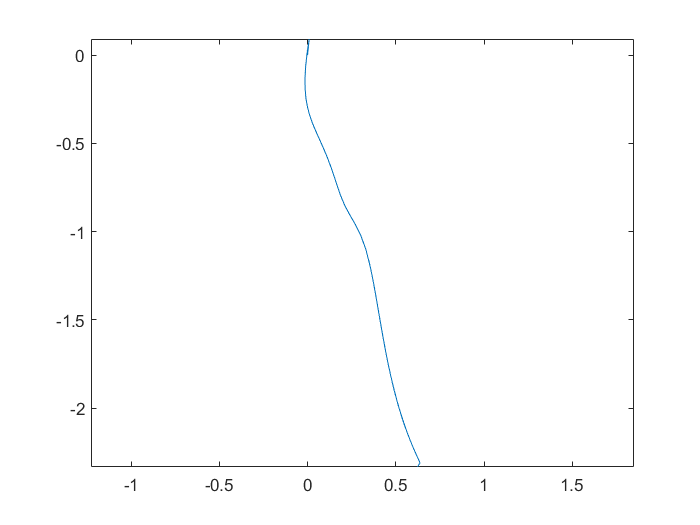

r_0 = [0, 0];
lambda = 1/50;
delta = 0.9;
tolerance = 1e-3;
max_steps = 1000;

path = gradient_descent(grad_func, r_0, lambda, delta, tolerance, max_steps);
plot(path(:, 1), path(:, 2));
axis equal

path(end, :)

ans =     0.6228   -2.3337


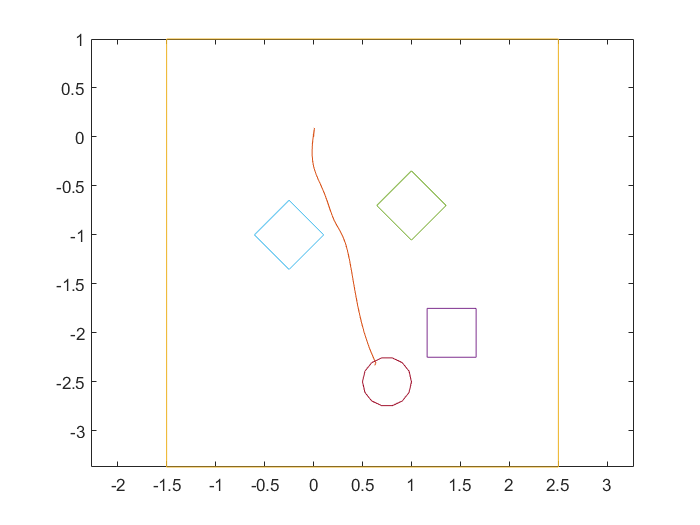


hold on
plot(path(:, 1), path(:, 2));
plot(w(:,1), w(:,2))
plot(s1(:,1), s1(:,2))
plot(s2(:,1), s2(:,2))
plot(s3(:,1), s3(:,2))
plot(bob(:,1), bob(:,2))
axis equal
hold off